# Implicit Deep Learning Tutorial on Synthetic Data

The impicit prediction rule reads


$$y=Ax+Bu+c\\
x=\phi(Dx+Eu+f)$$


we consider the well-posedness condition $\|D\|_\infty <1$. We consider the following dimensions $x\in R^h$, $u \in R^n$, $y \in R^p$ with matrices and vectors $A, B, c, D, E, f$ of corresponding appropriate dimensions. 

Let us start by drawing the real weights for the implicit model

n=10; h=100; p=5; density=0.3;
A=sprand(p,h,density).*(sign(rand(p,h)-0.5)); B=sprand(p,n,density).*(sign(rand(p,n)-0.5)); c=rand(p,1)-0.5;
D=sprand(h,h,density).*(sign(rand(h,h)-0.5)); E=sprand(h,n,density).*(sign(rand(h,n)-0.5)); f=rand(h,1)-0.5;
% project D to make it well-posed
funcs=UtilitiesIDL;
D=funcs.infty_norm_projection(D);

We denote $m$ the number of datapoints, we create our synthetic datatset. We consider that $u \sim \mathcal{N}(0,\Sigma_{\text{train}})$, where $\Sigma_{\text{train}}$ is a covariance matrix

Mat=funcs.RandOrthMat(n); Sigma_train=Mat'*diag(n*rand(n,1))*Mat; clear Mat;
% num of datapoint
m=10^3;
U = mvnrnd(zeros(n,1),Sigma_train,m)'; clear Sigma_train;
% find corresponding X using Picard iterations
X=funcs.picard_iterations(U,D,E,f);
Y=A*X+B*U+c*ones(1,m);

## (1) Training Using the Implicit Model

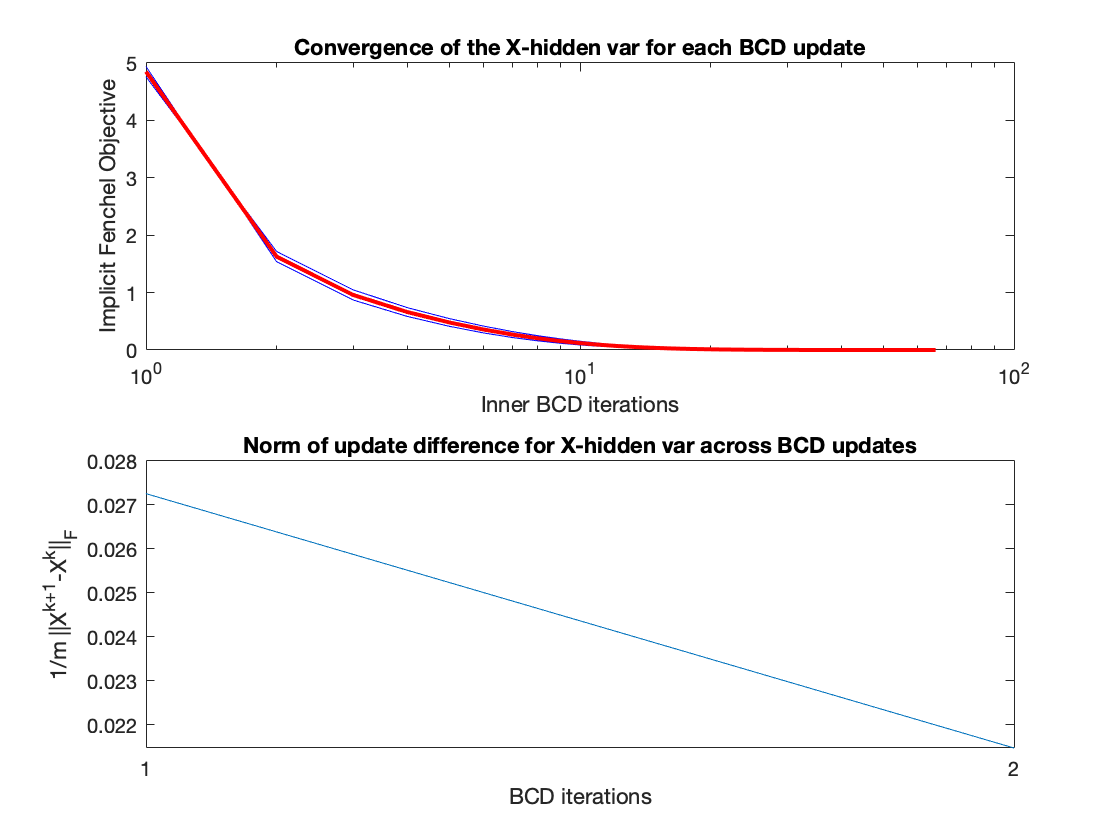

idl=ImplicitDeepLearning(U,Y,h); idl=idl.initial_train; 
idl.visualize_algo

## (2) Linear model fit for comparison

We solve the following convex optimization problem instead (as a comparison)


$$\min_{B_{lin},c_{lin}}\|B_{lin}U+c_{lin}-Y\|_F$$


cvx_begin 
variable B_lin(p,n) 
variable c_lin(p,1)
minimize((1/sqrt(m))*norm(B_lin*U+c_lin*ones(1,m)-Y,'fro'))
cvx_end

 
Calling SDPT3 4.0: 5001 variables, 56 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 56
 dim. of socp   var  = 5001,   num. of socp blk  =  1
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|6.9e+01|1.4e+00|2.9e+04| 0.000000e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|0.966|1.000|2.3e+00|2.4e-04|1.1e+03|-3.167193e+00 -1.462362e+01| 0:0:00| chol  1  1 
 2|0.998|1.000|3.7e-03|2.4e-05|1.5e+01|-1.509733e+00 -1.428844e+01| 0:0:00| chol  1  1 
 3|1.000|0.879|1.2e-09|7.5e-04|1.4e+00|-3.419788e+00 -4.778

Y_lin=B_lin*U+c_lin*ones(1,m);
disp(['The RMSE for the linear model is: ',num2str(funcs.RMSE(Y,Y_lin))]);

The RMSE for the linear model is: 4.6108


## (3) Neural Network Prediction rule for comparison

We fit a feedforward neural network model with 3 hidden layers of width $h$ (i.e. the total dimension of the hidden layer is $3h$ )

layers = [
    sequenceInputLayer(n)
    fullyConnectedLayer(h)
    reluLayer 
    fullyConnectedLayer(h)
    reluLayer
    fullyConnectedLayer(h)
    reluLayer
    fullyConnectedLayer(p)
    regressionLayer];

options = trainingOptions('rmsprop','MaxEpochs',10^3,'MiniBatchSize',m,'InitialLearnRate',10^-3);
net = trainNetwork(U,Y,layers,options);

Training on single CPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:00 |        13.05 |         85.1 |          0.0010 |
|      50 |          50 |       00:00:00 |         2.71 |          3.7 |          0.0010 |
|     100 |         100 |       00:00:01 |         2.02 |          2.0 |          0.0010 |
|     150 |         150 |       00:00:01 |         1.84 |          1.7 |          0.0010 |
|     200 |         200 |       00:00:02 |         1.57 |          1.2 |          0.0010 |
|     250 |         250 |       00:00:03 |         1.70 |          1.4 |          0.0010 |
|     300 |         300 |       00:00:03 |         1.44 |         